# TDA analysis of HCP Individual Contrasts

% Set project root
projectRoot = ''; 

% Add access to brain connectivity toolbocx (BCT)
bctFolder = fullfile(projectRoot, 'Code', '2019_03_03_BCT');
addpath(genpath(bctFolder));

% Build file/folder paths
behavFile = fullfile(projectRoot, 'HCP_behaviouraldata.xlsx');
tfmriFolder = fullfile(projectRoot, 'individual_tfmri_csv', 'output');
sub1File = fullfile(projectRoot, 'matching_sub1.csv');
sub2File = fullfile(projectRoot, 'matching_sub2.csv');

% Get subject numbers from filenames
files = dir(fullfile(tfmriFolder, '*_FAoutput.rds'));
subject_numbers = erase({files.name}, '_FAoutput.rds');

% Load logic for cohort 1 and 2
sub1_logic = readtable(sub1File);
sub2_logic = readtable(sub2File);

% Load contrast matrix of cohorts
load(fullfile(projectRoot, 'contrasts_all_2d_sub1.mat'));     % N×347
contrasts_all_2d_sub1 = data;
load(fullfile(projectRoot, 'row_labels_sub1.mat'));           % cell array of N
row_labels_sub1 = rowNames;

load(fullfile(projectRoot, 'contrasts_all_2d_sub2.mat'));     % M×347
contrasts_all_2d_sub2 = data;
load(fullfile(projectRoot, 'row_labels_sub2.mat'));           % cell array of M
row_labels_sub2 = rowNames;

## Specify cohort 1 or 2

cohort = 1; % 1 or 2

if cohort == 1
    data = contrasts_all_2d_sub1;
    rowNames = row_labels_sub1;
    suffix = '1';
elseif cohort == 2
    data = contrasts_all_2d_sub2;
    rowNames = row_labels_sub2;
    suffix = '2';
else
    disp("Specify cohort")
end

## Demean and normalize contrast data

% demean participants based on individual scores
subject_ids = cellfun(@(x) split(x, '_'), rowNames, 'UniformOutput', false);
subject_ids = cellfun(@(x) x{2}, subject_ids, 'UniformOutput', false);
subject_ids_numeric = cellfun(@str2double, subject_ids);

data_zscore_subjwise = [];
for s = 1:1:max(subject_ids_numeric)
    tmp = find(subject_ids_numeric==s);
    data_zscore_subjwise = [data_zscore_subjwise; zscore(data(tmp,:))];
end
data = data_zscore_subjwise;

% check for dead columns
bad_columns = find(var(data) == 0)


bad_columns =

  1×0 empty double row vector



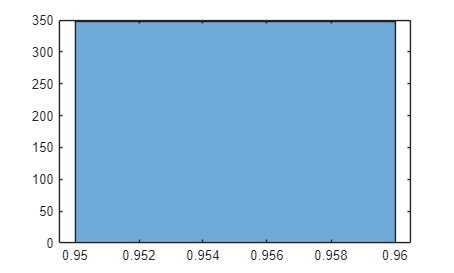

data(:,bad_columns) = [];

column_variances = var(data, 0, 1); 
figure;
histogram(column_variances, 'BinWidth', 0.01);

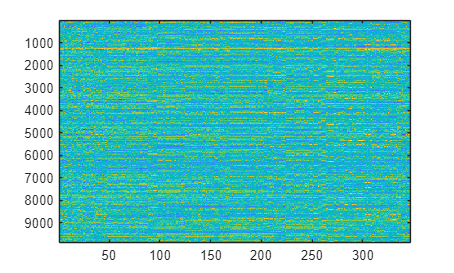


imagesc(data)

## 1) RDoC domain labeled contrast mapper

## Specify cohort 1 or 2 for subsequent analyses

cohort = 1; % 1 or 2

% Specify rdochcp_contrastmapper_subs1 or ..._subs2 for cohort 1 or cohort 2 
if cohort == 1
    load('rdochcp_contrastmapper_subs1.mat');
    suffix = '1';
elseif cohort == 2
    load('rdochcp_contrastmapper_subs2.mat');
    suffix = '2';
else
    disp("Specify cohort")
end

## Plot RDoC Mapper graph

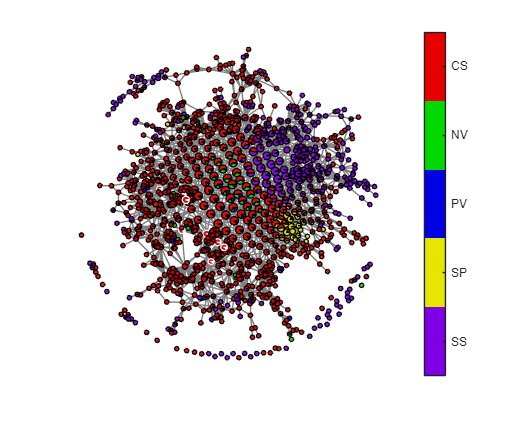

Elapsed time is 8.085254 seconds.


% Control conditions are CS
labels = {'NV-E1', 'CS-E2', 'NV-G1', 'PV-G2', 'CS-L1', 'CS-L2', 'CS-M1', 'SS-M2', 'SS-M3', 'SS-M4', 'SS-M5', 'SS-M6', 'CS-R1', 'CS-R2', 'CS-S1', 'SP-S2', 'CS-W1', 'CS-W2', 'CS-W3', 'CS-W4', 'CS-W5', 'CS-W6', 'CS-W7', 'CS-W8'};

% Get unique domains and assign each a numeric index
domains_rdoc = cellfun(@(x) x(1:2), labels, 'UniformOutput', false);
[unique_domains_rdoc, ~, domain_indices_rdoc] = unique(domains_rdoc);

% Determine number of subjects and maps
[n_nodes, n_total_maps] = size(nodeTpMat);
n_maps_per_subject = 24;
n_subjects = n_total_maps / n_maps_per_subject;

% Check divisibility
if mod(n_total_maps, n_maps_per_subject) ~= 0
    error('nodeTpMat columns not divisible by 24. Check input data.');
end

% Repeat domain index for each subject
domain_indices_all_rows = repmat(domain_indices_rdoc(:), n_subjects, 1);
comm = domain_indices_all_rows;

[nodeComm, prop_nodes] = computeProportionCategorical(nodeTpMat, comm); %color_indices links each factor with the highest loading map
[hubness90, hubness95, hubness99] = computeHubness(nodeBynode, degrees_und(nodeBynode));

color = [
    .9, 0, 0;     % Red
    0, .85, 0;     % Green
    0, 0, .9;     % Blue
    .9, .9, 0;     % Yellow
    .5, 0, .9     % Purple
    % .6, .6, .6      % Controls
];

saveit = 1; % 1 to save, 0 to not save
drawd3graph(nodeBynode, nodeComm, prop_nodes, color, fullfile(projectRoot, sprintf('figures/rdochcp_contrastmapper_rdoc%s_NVG1', suffix)), hubness90, unique_domains_rdoc, saveit);

## Calculate modularity

modularity = calMod(nodeBynode, nodeComm)
n_iter = 100;
rng("default")
[p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
saveas(gcf, fullfile(projectRoot, sprintf('figures/modularity_contrastmapper_rdoc%s.png', suffix)));

## Compute correlation of RDoC Mapper prop_nodes

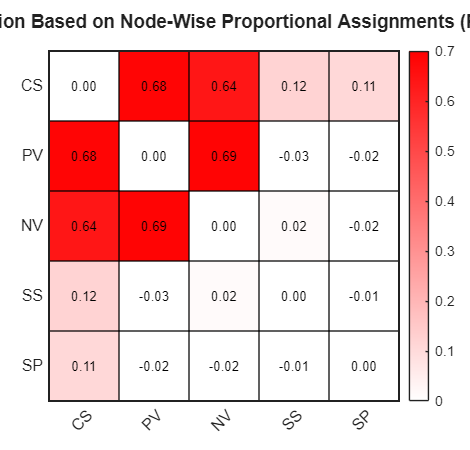

% Compute correlation matrix
R = corr(prop_nodes);

% Set diagonal to 0
R(1:size(R,1)+1:end) = 0;

% Compute row + column sums
row_col_sums = sum(R, 2) + sum(R, 1)';  % column vector
[~, new_order] = sort(row_col_sums, 'descend');

% Reorder R
R_sorted = R(new_order, new_order);
labels_sorted = unique_domains_rdoc(new_order);
row_sums_sorted = sum(R_sorted, 2);

cell_size = 70;
plot_fixed_square_heatmap(R_sorted, labels_sorted, labels_sorted, ...
    'Correlation Based on Node-Wise Proportional Assignments (RDoC)', ...
    [100, 100], cell_size, ...
    [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'], ...
    [0, 0.7], ...
    fullfile(projectRoot, sprintf('figures/corrpropnode_rdoc%s_NVG1.png', suffix)));

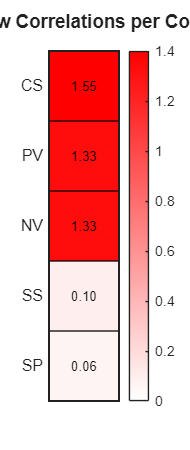


% --- Figure 2: Single-Column Sum Heatmap ---
plot_fixed_square_heatmap(row_sums_sorted, '', labels_sorted, ...
    'Sum of Row Correlations per Community', ...
    [750, 100], cell_size, ...
    [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'], ...
    [0, 1.4], ...
    fullfile(projectRoot, sprintf('figures/corrsum_rdoc%s_NVG1.png', suffix)));

## 2) Data-driven community labeled contrast mapper

## Specify cohort 1 or 2 for subsequent analyses

cohort = 1; % 1 or 2

% Load community centroids of cohort 1 and 2
load(fullfile(projectRoot, 'comm_centroid1.mat')); % fscores 
% load(fullfile(projectRoot, 'comm_centroid2.mat')); % fscores

% Load _sub1 or _sub2 for cohort 1 or 2 for subsequent analyses
if cohort == 1
    load('rdochcp_contrastmapper_subs1.mat');
    load(fullfile(projectRoot, 'rdochcp_allsubs1_community.mat')); % Load communities from R code
    factor_data = readtable(fullfile(projectRoot, 'ddfactors_subs1_nog_hcp.xlsx'));
    comm_centroid = comm_centroid1;
    suffix = '1';
elseif cohort == 2
    load('rdochcp_contrastmapper_subs2.mat');
    load(fullfile(projectRoot, 'rdochcp_allsubs2_community.mat')); % Load communities from R code
    factor_data = readtable(fullfile(projectRoot, 'ddfactors_subs2_nog_hcp.xlsx'));
    comm_centroid = comm_centroid2;
    suffix = '2';
else
    disp("Specify cohort")
end

## Showing communities across factor scores

% Demean participants based on individual scores
rowNames = factor_data{:, 1};
factor_data(:, 1) = [];
factor_data.Properties.RowNames = rowNames;
factor_data = factor_data{:, :}; %turns the table into an array

subject_ids = cellfun(@(x) split(x, '_'), rowNames, 'UniformOutput', false);
subject_ids = cellfun(@(x) x{2}, subject_ids, 'UniformOutput', false);
subject_ids_numeric = cellfun(@str2double, subject_ids);

factor_data_zscore_subjwise = [];
for s = 1:1:max(subject_ids_numeric)
    tmp = find(subject_ids_numeric==s);
    factor_data_zscore_subjwise = [factor_data_zscore_subjwise; zscore(factor_data(tmp,:))];

end
factor_data = factor_data_zscore_subjwise;

max(ciu) % This should be 4/5 modules for cohort 1/2 respectively

ans = 4

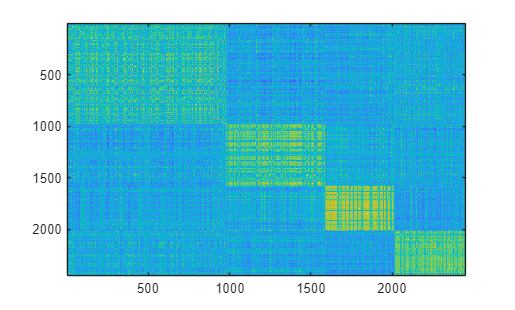

[comm, comm2, ~] = arrangeComm(ciu, corr(factor_data'));
imagesc(comm) %visualizing the communities

## Plot Data-driven Mapper graph

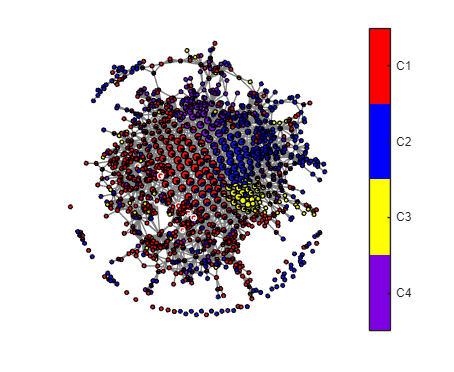

Elapsed time is 0.000082 seconds.


% Reorder the community centroids of cohort 2 to 1a, 1b, 2, 3, 4 to match the 4 centroids in cohort 1
if size(comm_centroid, 1) == 5
    comm_centroid = comm_centroid([1 5 3 2 4], :); 
end

% Compute correlation between each row of data and each centroid
n_rows = size(data, 1);
n_centroids = size(comm_centroid, 1);

correlations = zeros(n_rows, n_centroids);

for i = 1:n_centroids
    % Compute correlation between each row in data and the i-th centroid
    c = corr(data', comm_centroid(i, :)');  % returns 9888 x 1
    correlations(:, i) = c;
end

% Get index of the max correlation for each row
[~, best_centroid_idx] = max(correlations, [], 2);  % 9888 x 1
comm = best_centroid_idx;

if size(comm_centroid, 1) == 4
    unique_comms = {"C1", "C2", "C3", "C4"};
elseif size(comm_centroid, 1) == 5
    unique_comms = {"C1a", "C1b", "C2", "C3", "C4"};
end 

[nodeComm, prop_nodes] = computeProportionCategorical(nodeTpMat, comm); %color_indices links each factor with the highest loading map
[hubness90, hubness95, hubness99] = computeHubness(nodeBynode, degrees_und(nodeBynode));

if size(comm_centroid, 1) == 5
color = [
    1, 0, 0;   % Red
    0, 1, 0;   % Green
    0, 0, 1;   % Blue
    1, 1, 0;    % Yellow
    .5, 0, .9;    % Purple
];
elseif size(comm_centroid, 1) == 4
    color = [
    1, 0, 0;   % Red
    0, 0, 1;   % Blue
    1, 1, 0;    % Yellow
    .5, 0, .9;    % Purple
];
end 

saveit = 0; % 0 to not save, 1 to save
drawd3graph(nodeBynode, nodeComm, prop_nodes, color, fullfile(projectRoot, sprintf('figures/rdochcp_contrastmapper_comm%s', suffix)), hubness90, unique_comms, saveit);

% Calculate modularity
modularity = calMod(nodeBynode, nodeComm)

modularity = 0.3803

n_iter = 5000;
rng("default")
[p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
saveas(gcf, fullfile(projectRoot, sprintf('figures/modularity_contrastmapper_comm%s.png', suffix)));

## Compute correlation of Data-driven Mapper prop_nodes

modularity = calMod(nodeBynode, nodeComm)
n_iter = 5000;
rng("default")
% [p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
% saveas(gcf, fullfile(projectRoot, 'figures', 'modularity_contrastmapper_comm2.png');

% Compute off-diagonal correlation matrix
R = corr(prop_nodes);
R(1:size(R,1)+1:end) = 0;  % Set diagonal to NaN

% Compute row + column sums
row_col_sums = sum(R, 2) + sum(R, 1)';
[~, sort_idx] = sort(row_col_sums, 'descend');

% Reorder R and labels
R_sorted = R(sort_idx, sort_idx);
labels_sorted = unique_comms(sort_idx);
row_sums_sorted = sum(R_sorted, 2);  % for single-column heatmap

% Define appearance
cell_size = 70;
cmap = [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'];

% ---- Figure 1: full matrix ----
plot_fixed_square_heatmap(R_sorted, labels_sorted, labels_sorted, ...
    'Correlation Based on Node-Wise Proportional Assignments (DD)', ...
    [100, 100], cell_size, cmap, [0, 0.7], ...
    fullfile(projectRoot, sprintf('figures/corrprop_contrastmapper_comm%s.png', suffix)));

% % ---- Figure 2: row sums ----
plot_fixed_square_heatmap(row_sums_sorted, '', labels_sorted, ...
    'Sum of Row Correlations per Community', ...
    [750, 100], cell_size, cmap, ...
    [0, 1.4], ...
    fullfile(projectRoot, sprintf('figures/corrsum_contrastmapper_comm%s.png', suffix)));

## 3) Violin plots of jackknife bootstrap modularity

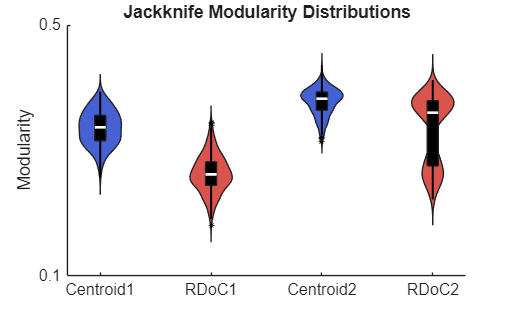

load(fullfile(projectRoot, 'modularity_jackknife_results_NVG1')) % Cohort 1 results from Jackknife bootstrapping R code 
load(fullfile(projectRoot, 'modularity_jackknife_results_NVG1_sub2')) % Cohort 2 results from Jackknife bootstrapping R code

% Get lengths
n1 = length(mod_centroid_sub1);
n2 = length(mod_centroid_sub2);
n_max = max(n1, n2);

% Pad with NaNs to match length
mod_centroid_sub2(end+1:n_max,1) = NaN;
mod_rdoc_sub2(end+1:n_max,1) = NaN;

% Concatenate
Y = [mod_centroid_sub1, mod_rdoc_sub1, mod_centroid_sub2, mod_rdoc_sub2];

% Define a unique group for each column to apply per-column coloring
group_idx = [1, 2, 3, 4];  % fake group labels to force 4 colors

% Define 4 colors: [Centroid Sub1, RDoC Sub1, Centroid Sub2, RDoC Sub2]
color_centroid = [0.27, 0.38, 0.83];  % blue
color_rdoc     = [0.85, 0.33, 0.30];  % red
colors = [color_centroid; color_rdoc; color_centroid; color_rdoc];

% Repeat group labels for each data point
groups = repelem(group_idx, size(Y, 1))';

% Reshape data and group vector for column-wise input
Y_flat = Y(:);
group_labels = repelem(1:4, size(Y,1))';

% Prepare as matrix with one column and set group vector
figure;
daviolinplot(Y_flat, 'groups', group_labels, ...
    'colors', colors, ...
    'violin', 'full', ...
    'box', 2, ...
    'xtlabels', {'Centroid1', 'RDoC1', 'Centroid2', 'RDoC2'});
ylim([0.1 0.5]);
yticks([0.1 0.5]);
ylabel('Modularity');
title('Jackknife Modularity Distributions');
set(gca, 'FontSize', 12);


% Save the plot
% saveas(gcf, fullfile(projectRoot, 'figures', 'modularity_jackknifebs_NVG1_violinplot.png'));

## Wilcoxon signed-rank test

% Test for Sub1
[p_sub1, h_sub1, stats_sub1] = signrank(mod_centroid_sub1, mod_rdoc_sub1);
% Test for Sub2
[p_sub2, h_sub2, stats_sub2] = signrank(mod_centroid_sub2, mod_rdoc_sub2);

fprintf('Sub1 Centroid vs RDoC: p = %.4f, z = %.2f\n', p_sub1, stats_sub1.zval);

Sub1 Centroid vs RDoC: p = 0.0000, z = 17.59


fprintf('Sub2 Centroid vs RDoC: p = %.4f, z = %.2f\n', p_sub2, stats_sub2.zval);

Sub2 Centroid vs RDoC: p = 0.0000, z = 14.76



% Paired t-test for Sub1
[~, p_sub1, ~, stats_sub1] = ttest(mod_centroid_sub1, mod_rdoc_sub1);
% Paired t-test for Sub2
[~, p_sub2, ~, stats_sub2] = ttest(mod_centroid_sub2, mod_rdoc_sub2);

fprintf('Sub1 Centroid vs RDoC: p = %.4f, t = %.2f, df = %d\n', ...
    p_sub1, stats_sub1.tstat, stats_sub1.df);

Sub1 Centroid vs RDoC: p = 0.0000, t = 79.63, df = 411


fprintf('Sub2 Centroid vs RDoC: p = %.4f, t = %.2f, df = %d\n', ...
    p_sub2, stats_sub2.tstat, stats_sub2.df);

Sub2 Centroid vs RDoC: p = 0.0000, t = 19.98, df = 328
